# Homework 5

## ADSI Problem 4.2: Autocorrelation functions from plot

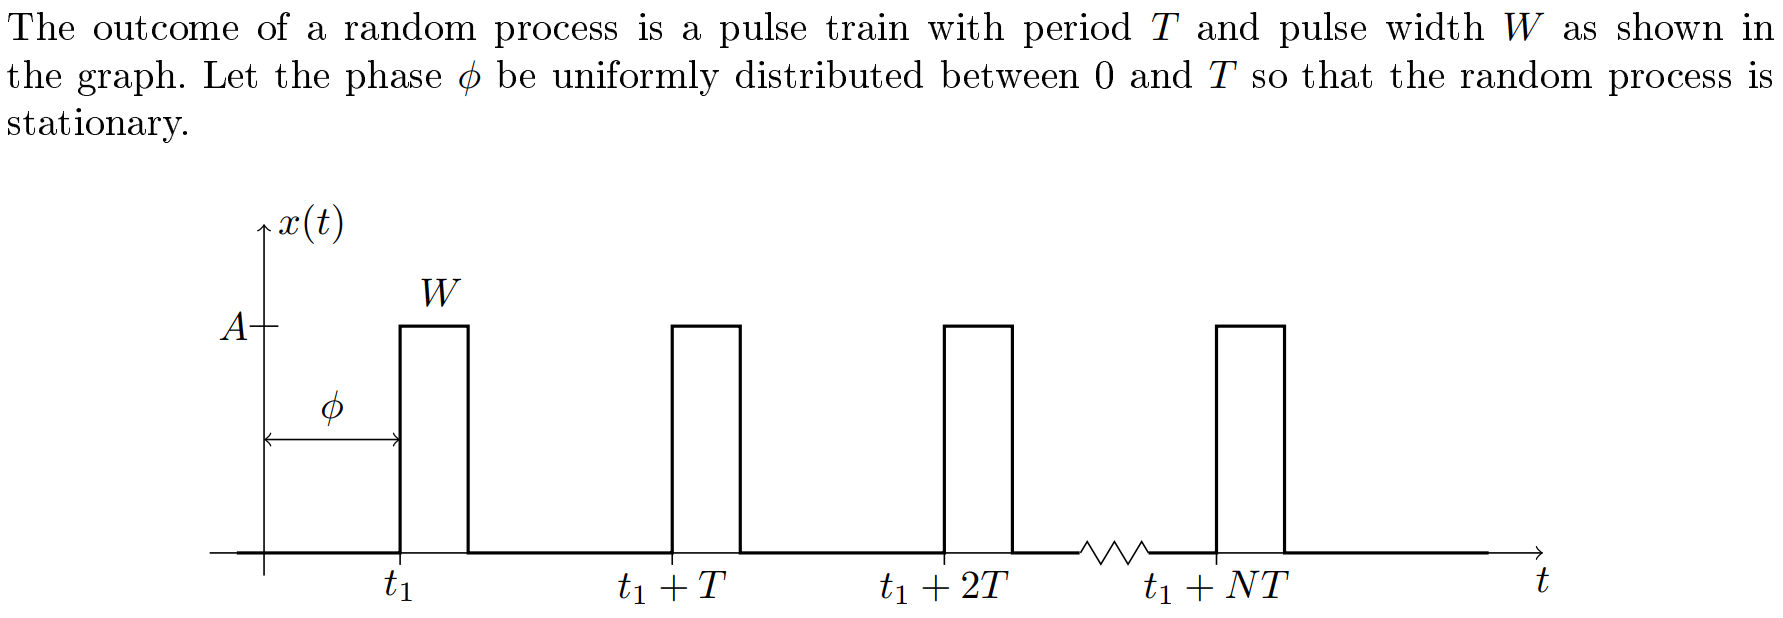

### 1) Sketch and explain what the autocorrelation looks like

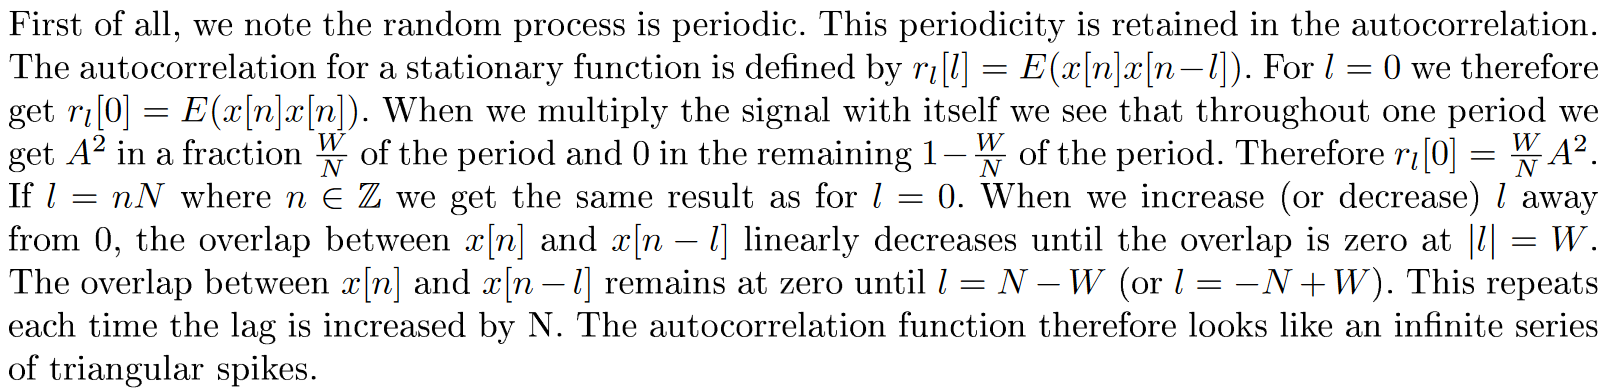

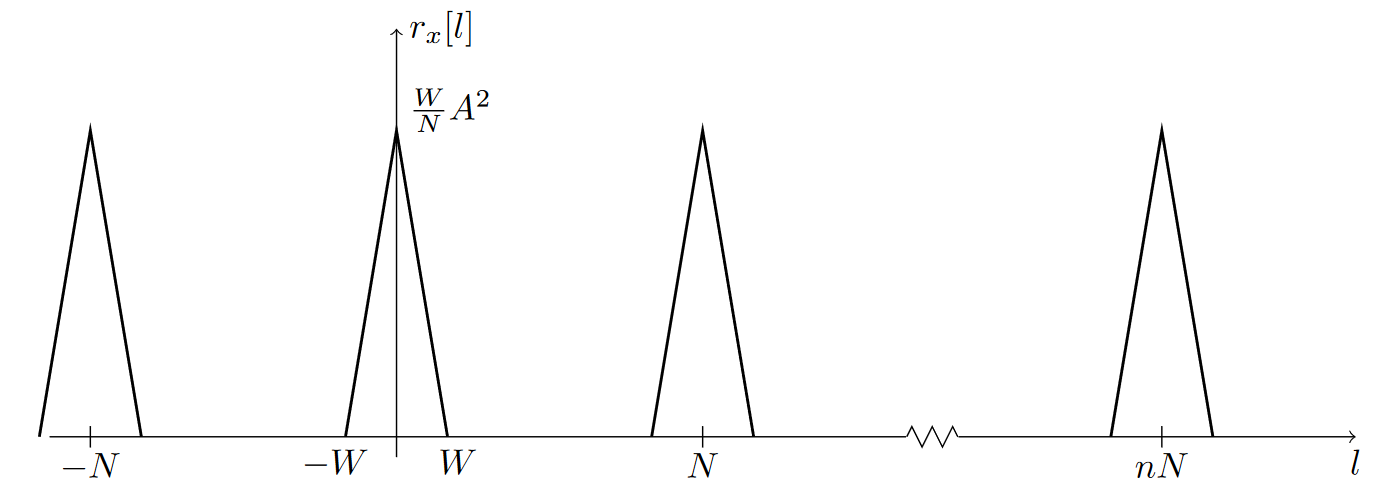

### [✔] 2) Use computer simulations to verify the above result

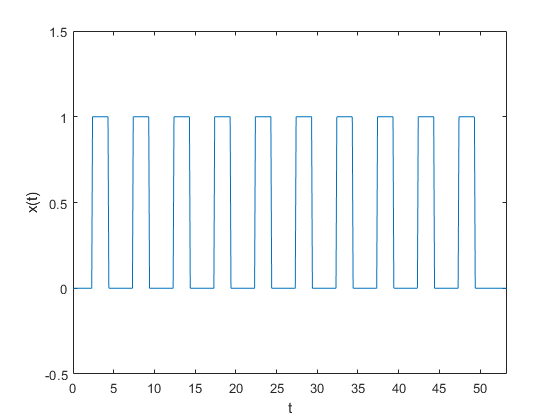

A = 1;
W = 2;  % Pulse width
T = 5; % Period width
N = 10;

% Random number from a uniform distribution in the open interval (a, b)
% a = 0; b = T; random_number = (b-a)*rand + a
phi = T*rand(1);

maxT = phi+W/2 + T*N;

t=0:.1:maxT;   % Time vector 
d= phi+W/2:T:phi+W/2+T*N-1; % Delay vector
y = pulstran(t,d,'rectpuls', W);
plot(t,y)

ylabel('x(t)');
xlabel('t');
ylim([-0.5, A+0.5]);
xlim([0, max(t)]);

Autocorrelation is symmetrical around zero.

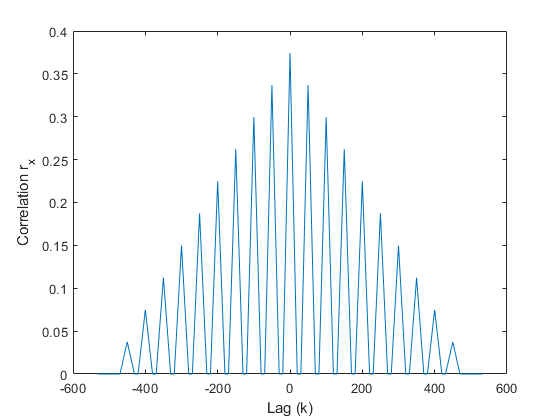

[r_xx, lags] = xcorr(y, 'biased');
plot(lags, r_xx);
ylabel('Correlation r_x');
xlabel('Lag (k)')

## ADSI Problem 4.4: Autocorrelation of complex signals

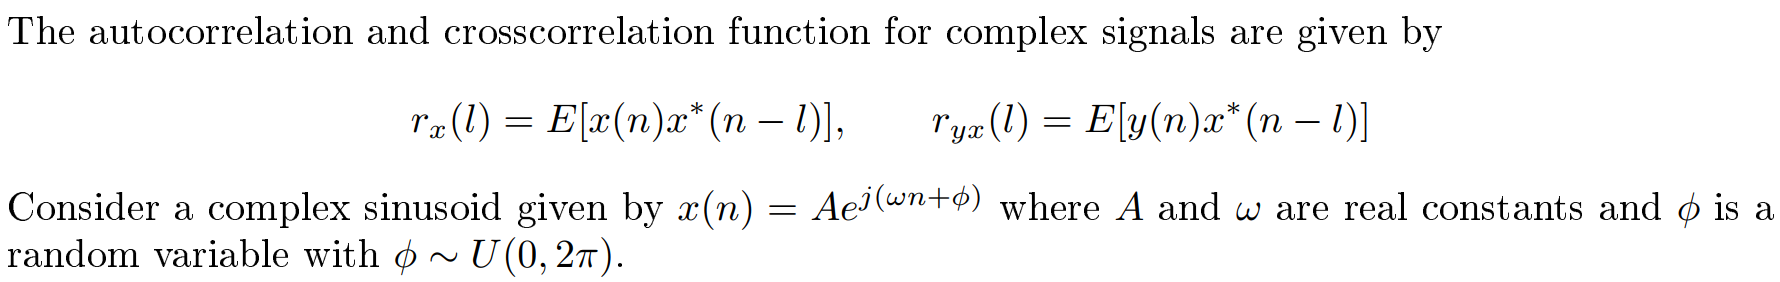

### 1) Compute the analytic expression for the autocorrelation of the complex sinusoid 

The autocorrelation function for complex signals can be computed as:


$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n-\ell \right)\right\rbrack$$


Plugging the given complex sinusiod into the formula, we get:


$$r_{\mathrm{xx}} \left(\ell \right)=E\left\lbrack A\;e^{j\left(\omega n+\phi \right)} A\;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$


Since $A$ is a constant, we can move it outside the expected value:


$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\left(\omega n+\phi \right)} \;e^{-j\left(\omega \left(n-\ell \right)+\phi \right)} \right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi } \;e^{-j\omega n+j\omega \ell -j\phi } \right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi +\left(-j\omega n+j\omega \ell -j\phi \right)} \;\right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega n+j\phi -j\omega n+j\omega \ell -j\phi } \;\right\rbrack$$



$$r_{\textrm{xx}} \left(\ell \right)=A^2 E\left\lbrack \;e^{j\omega \ell } \;\right\rbrack$$


According to the solution sheet, $E\left\lbrack e^{j\omega \ell } \right\rbrack =e^{j\omega \ell }$

**But why? **$\phi$ is not part of the expression.


$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


### [✔] 2) How are rx(l) and rx(-l) related for a complex signal?

In 1) we found an analytical expression for $r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell }$

Let us compute the autocorrelation for $-\ell$:


$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(n\right)x^* \left(n+\ell \right)\right\rbrack$$


Suppose $m=n+\ell$. Then we can write $n=m-\ell$. Let us substitute all $n$ with $m$ in the above expression:


$$r_{\textrm{xx}} \left(-\ell \right)=E\left\lbrack x\left(m-\ell \right)x^* \left(m\right)\right\rbrack$$


Computing the complex conjucate of the expectation we get:


$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x^* \left(m-\ell \right)x\left(m\right)\right\rbrack }^*$$



$$r_{\textrm{xx}} \left(-\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$$


Since $r_{\textrm{xx}}^* \left(\ell \right)=E{\left\lbrack x\left(m\right)x^* \left(m-\ell \right)\right\rbrack }^*$, we know that:


$$r_{\textrm{xx}} \left(-\ell \right)=r_{\textrm{xx}}^* \left(\ell \right)$$


### [✔] 3) Compute the autocorrelation of a real signal

We can use the result from 1)


$$r_{\textrm{xx}} \left(\ell \right)=A^2 \;e^{j\omega \ell } \;$$


Since the result from 1) uses Euler, we need to convert the signal to complex exponential. 

We use the relation $\mathrm{cos}\left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$


$$x\left(n\right)=A\;\mathrm{cos}\left(\omega \;n+\phi \right)$$



$$x\left(n\right)=\frac{A}{2}\;\left(e^{j\left(\omega n+\phi \right)} +e^{-j\left(\omega n+\phi \right)} \right)$$



$$x\left(n\right)=\frac{A}{2}e^{j\left(\omega n+\phi \right)} +\frac{A}{2}e^{-j\left(\omega n+\phi \right)}$$


In 1) we found that the autocorrelation of a complex sinusoid $x\left(n\right)=A\;e^{j\left(\omega \;n+\phi \right)}$ is $r_{\textrm{xx}} \left(\ell \right)=A^2 e^{j\omega \ell }$

Therefore, the autocorrelation of the real signal is:


$$r_{\mathrm{xx}} \left(\ell \right)={\left(\frac{A}{2}\right)}^2 e^{j\omega \ell } +{\left(\frac{A}{2}\right)}^2 e^{-j\omega \ell }$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}e^{j\omega \ell } +\frac{A^2 }{4}e^{-j\omega \ell }$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{4}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$



$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\frac{1}{2}\left(e^{j\omega \ell } +e^{-j\omega \ell } \right)$$


Using the relation $\cos \left(\theta \right)=\frac{1}{2}\left(e^{j\theta } +e^{-j\theta } \right)$  we can rewrite the autocorrelation to:


$$r_{\textrm{xx}} \left(\ell \right)=\frac{A^2 }{2}\mathrm{cos}\left(\omega \ell \right)$$


## ADSI Problem 4.5: Autocorrelation of distorted signals

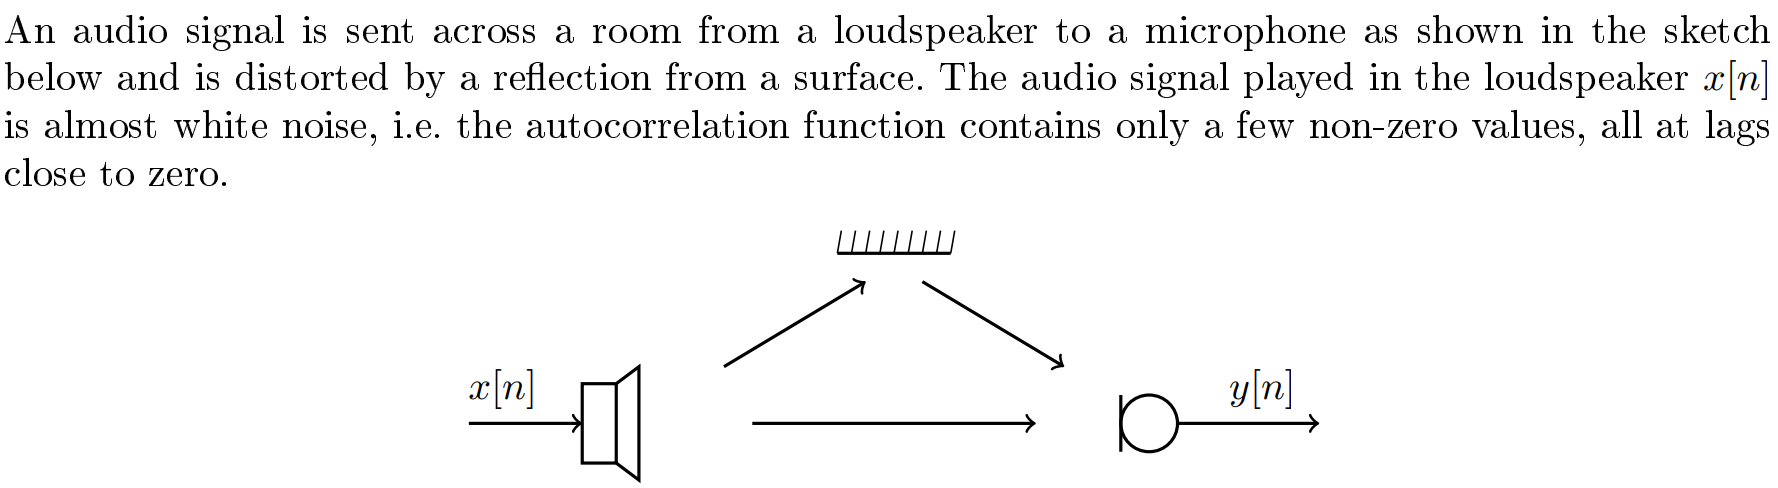

### 1) Derive autocorrelation function of the output signal

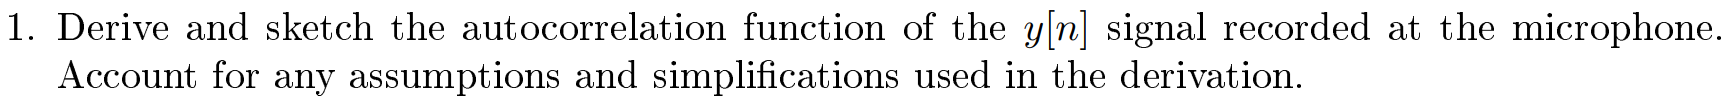

### 2) Is possible to remove the distortion from the output signal?

## ADSI Problem 4.6: System identification

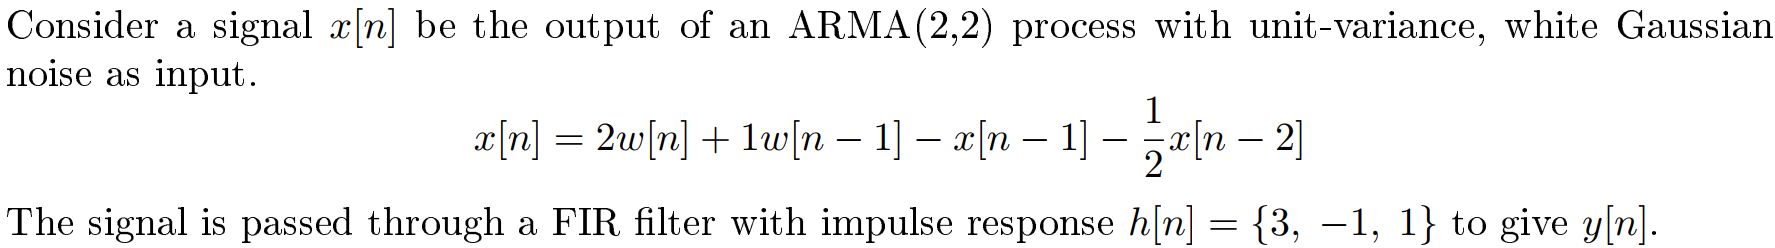

### 1) Simulate the autocorrelation and cross-correlation in MATLAB

### 2) Compute the transfer function and impulse response from the autocorrelation

## Exam 2012 Problem 4: Wiener filter for recovering corrupted signal

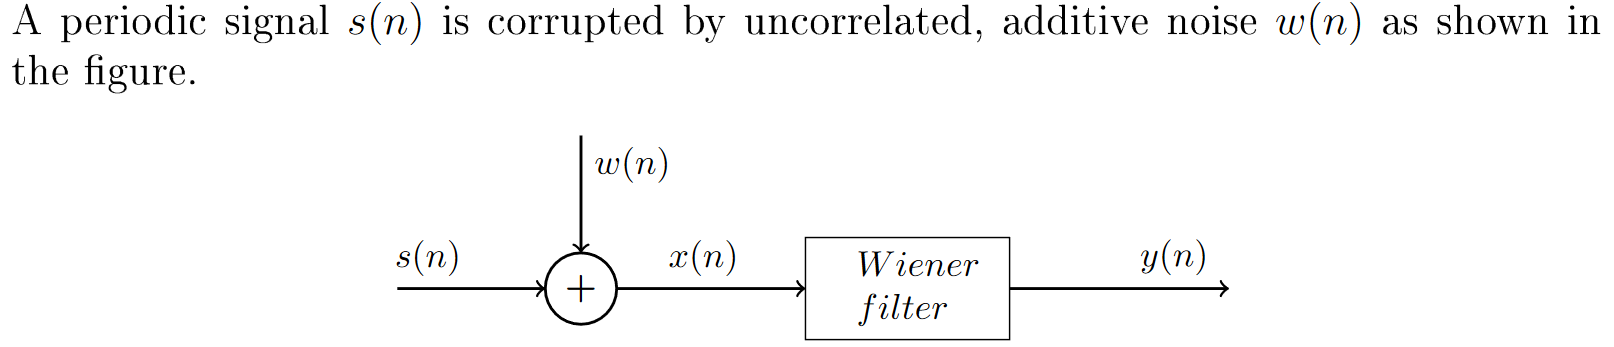

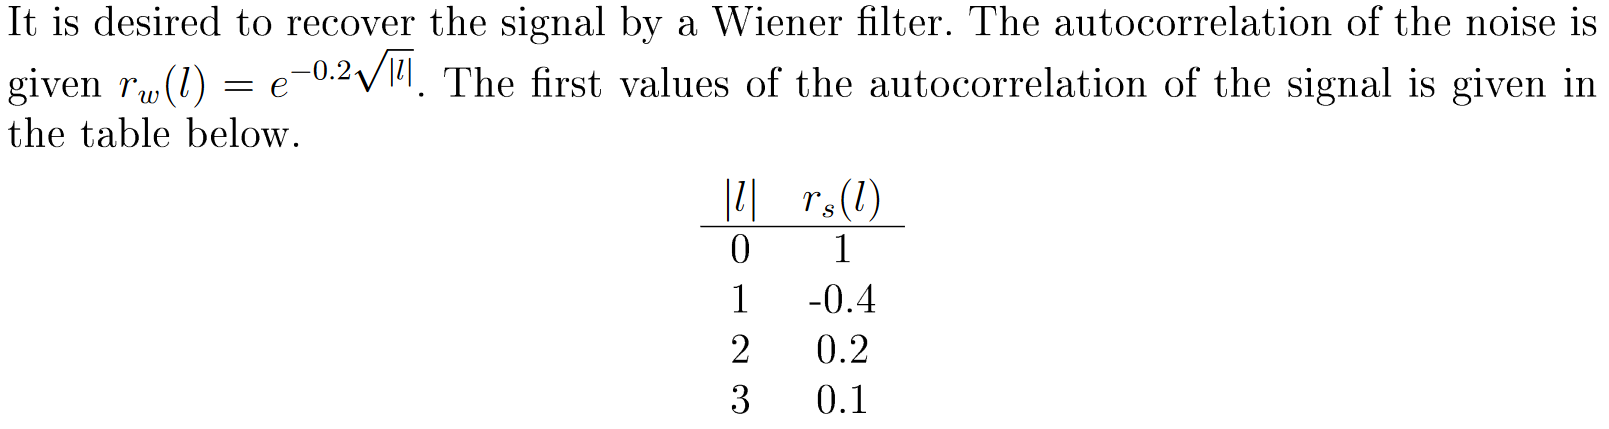

### 1) Design a 3 tap Wiener filter to recover s(n)

### 2) Calculate the minimum mean square error

### 3) Discuss another Wiener filter with 2x noise amplitude